初期状態の値(initial_generator_state)と状態定常値の差に関して、定常値に収束するための初期値誤差を調べ、その境界を探索する 

状態における誤差は　10^left　10^right  とおく  ( 例、left = -17 のとき 10^-17 ) 

( left: 最終状態値と状態定常値との差がゼロであるべき指数,  right: 最終状態値と状態定常値との差がゼロではない指数 )

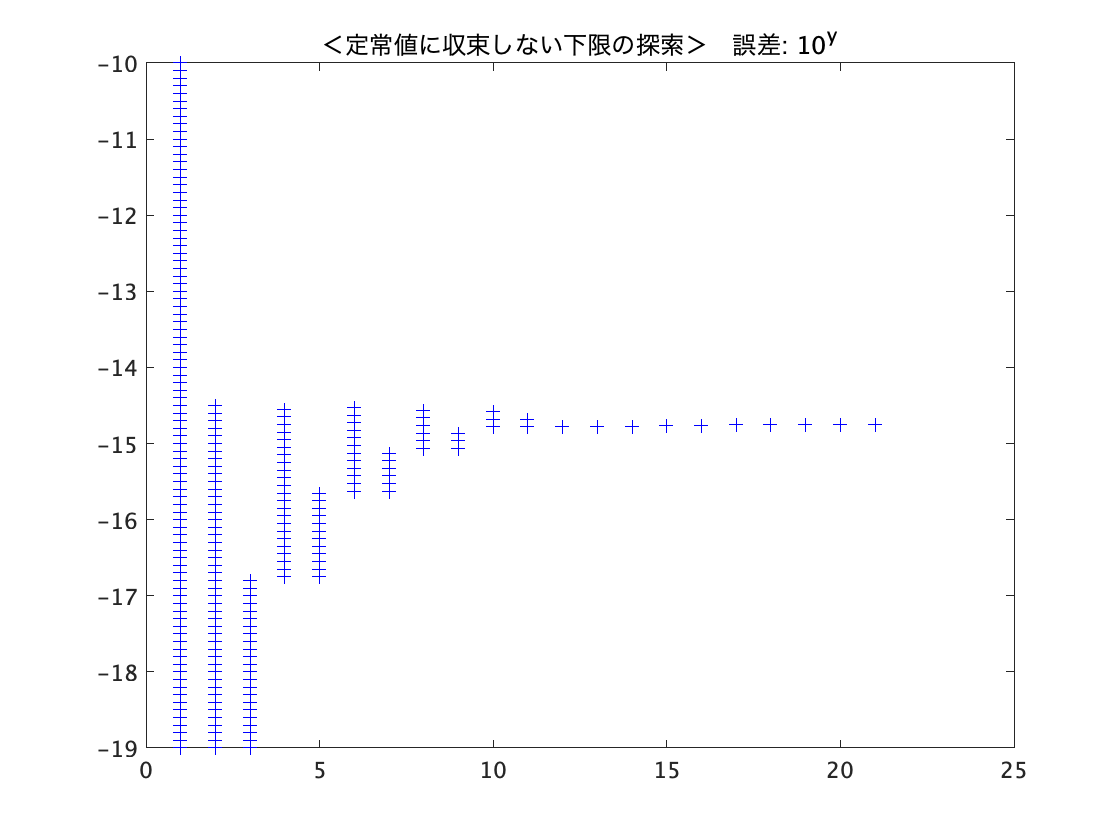

ans = 4

clear
left = -10;
right = -1;

tspan = [0 100];

%状態の初期値を設定
initial_delta = [61;34;52];
initial_E = [35;21;18];
initial_deltaomega = [0;0;0];
initial_generator_state = [initial_delta; initial_E; initial_deltaomega];

%最終時間における状態値と状態定常値の差を得る
get_final_error_wrap = @(error) get_final_error(error,tspan,initial_generator_state);

error_left = get_final_error_wrap(left);
error_right = get_final_error_wrap(right);

t = 1;
f1 = figure;
f2 = figure;

while max(abs(error_right(:))) > 1 | all(error_right(:)) == 0
    
    if all(error_left(:)) == 0 & any(error_right(:)) ~= 0
        
        %1
        
        right = (right + left) /2;
        
        if (right - left) < 0.001
            4
            break
        end
        
    elseif  all(error_right(:)) == 0
        
        %2
        
        temp = left;
        
        left = right;
        
        right = right + (right - temp);
        
    elseif any(error_left(:)) ~= 0
        
        %3
        
        temp = right;
        
        right = left;
        
        left = left - (temp - right);
      
    end
    %[left, right]
    figure(f1);
    plot(t,left:0.1:right,'b+')
    title('＜定常値に収束しない下限の探索＞　誤差: 10^y')
    hold on
    
    if max(abs(error_right(:))) > 0
        figure(f2);
        plot(t,max(abs(error_right(:))),'r*')
        title('定常値との最大誤差の絶対値')
        hold on
    end
    
    t = t + 1;
    
    error_left = get_final_error_wrap(left);
    error_right = get_final_error_wrap(right);

end

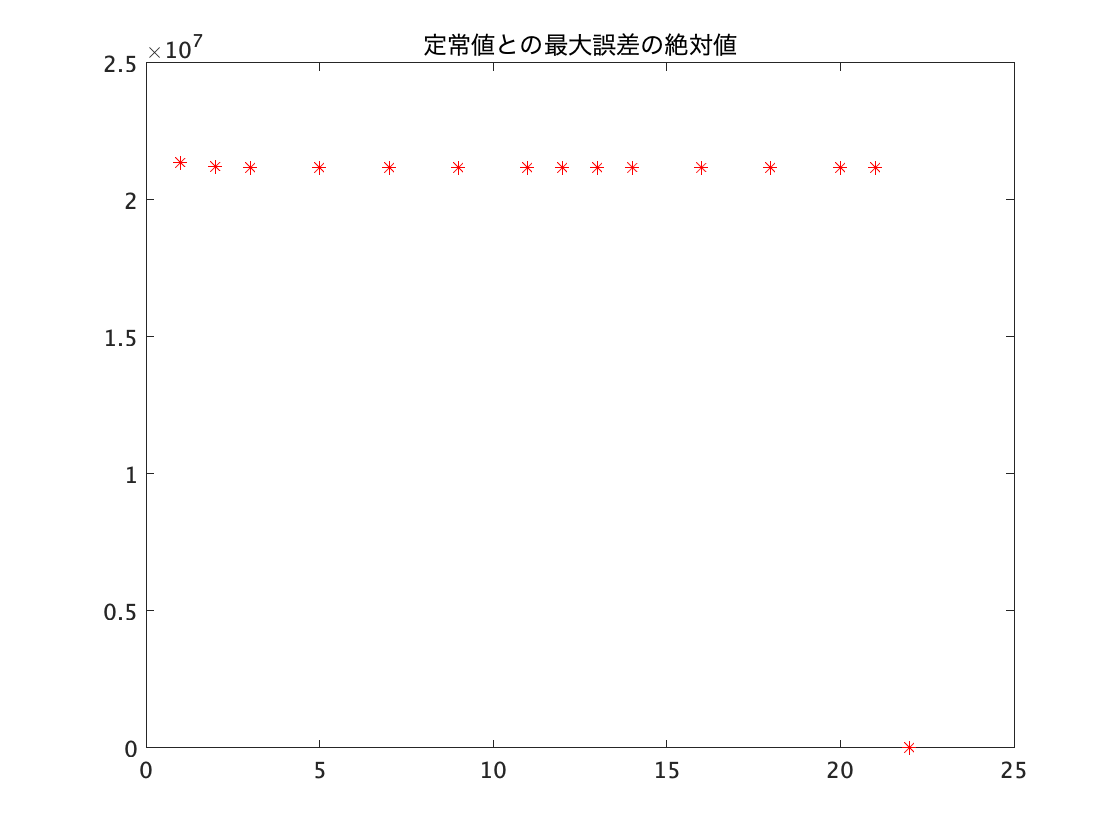

figure(f2);
plot(t,max(abs(error_left(:))),'r*')
hold off

right

right = -14.7499

left

left = -14.7505

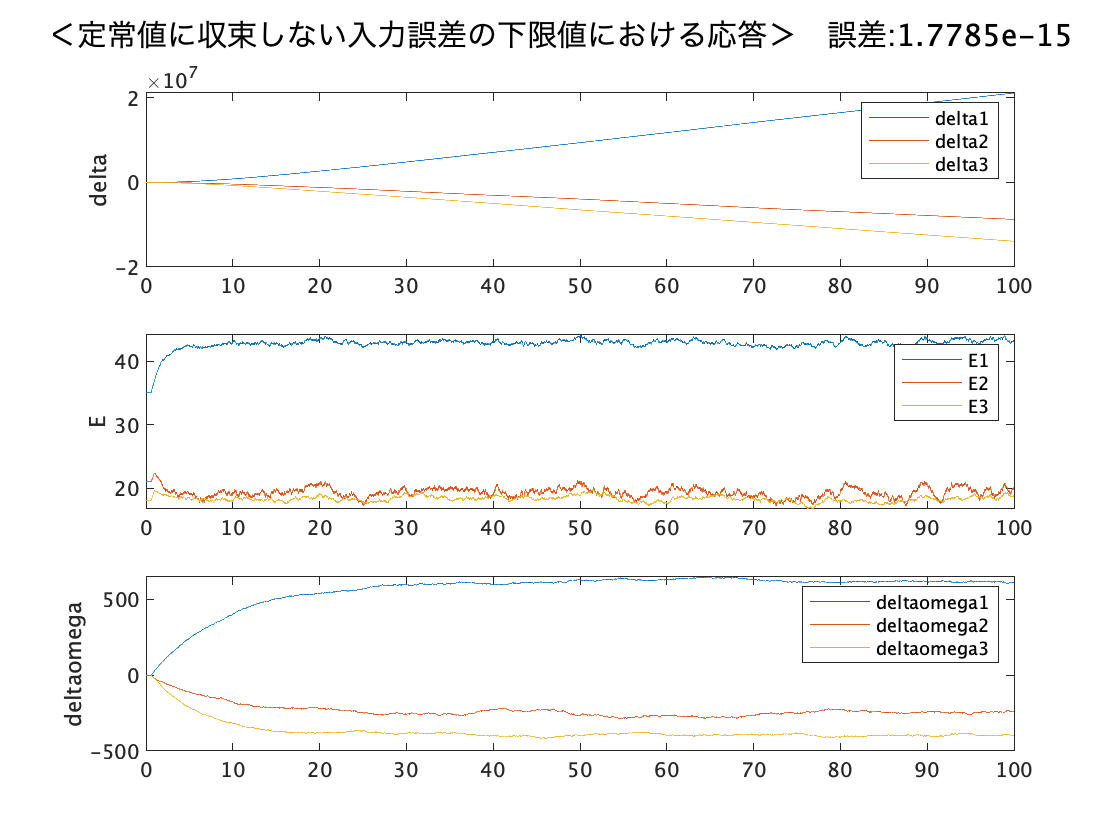

figure;
plot_generator_state(right,tspan,initial_generator_state)
sgtitle(['＜定常値に収束しない入力誤差の下限値における応答＞　初期誤差:',num2str(10^right)])

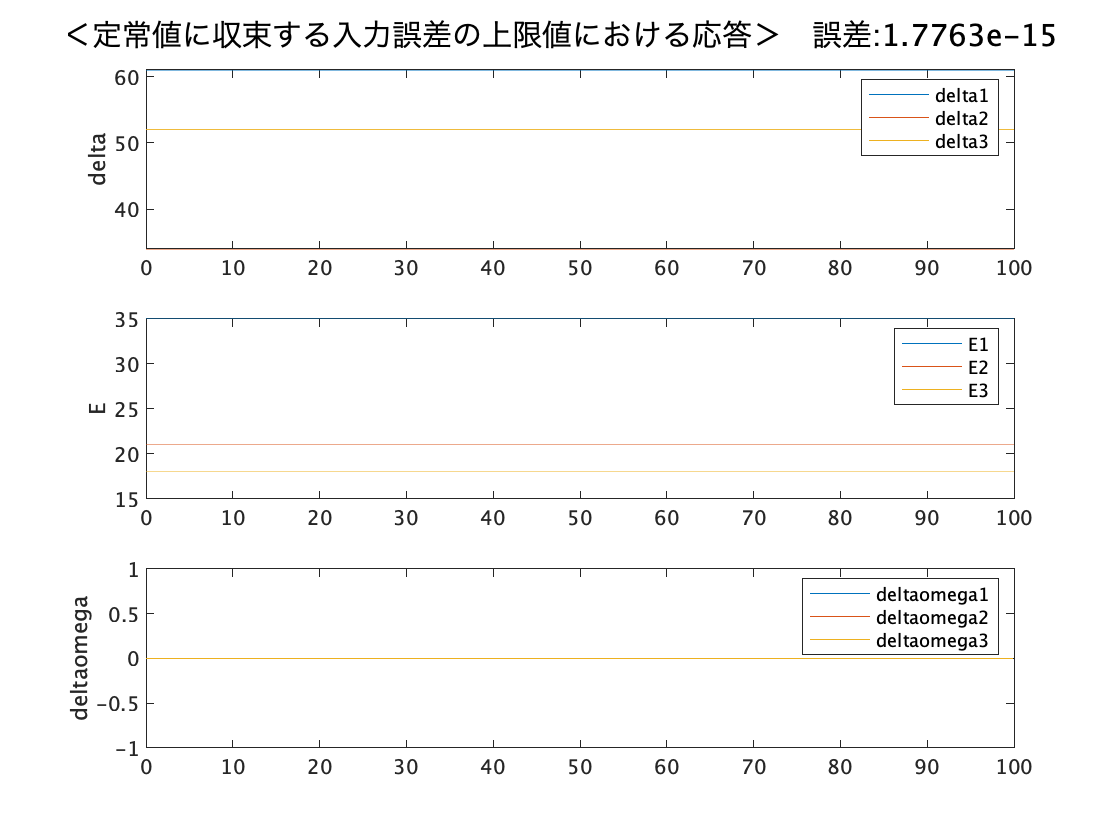

figure;
plot_generator_state(left,tspan,initial_generator_state)
sgtitle(['＜定常値に収束する入力誤差の上限値における応答＞　初期誤差:',num2str(10^left)])